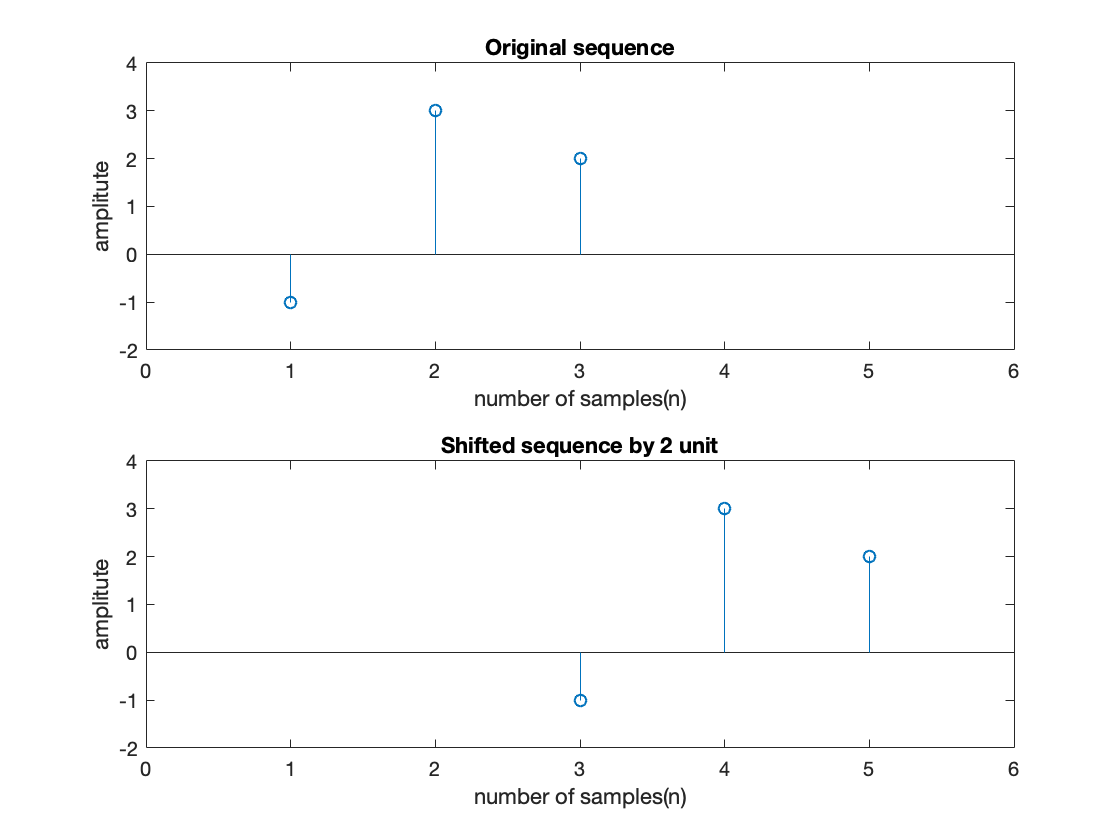

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to shift sequence 
%----------------------------------------------------------------------

close all;
clc;

%take sequence as an input
%I am assuming sequence starts from n = 1
seq = input('enter the sequence: '); %example input = [1 2 3 4 5]
seq_length = length(seq);
n = 1:1:seq_length;

%shift such that (n - n_d). Take n_d as input
n_d = input('Shift by: '); 

%plot given sequence
p1 = subplot(2,1,1);
stem(n, seq);
xlabel('number of samples(n)');
ylabel('amplitute');
title('Original sequence');
hold on;

%shift sequence and then plot the new sequence
shifted_seq = seq;
new_n = n + n_d;
p2 = subplot(2,1,2);
stem(new_n, shifted_seq);
xlabel('number of samples(n)');
ylabel('amplitute');
title(['Shifted sequence by ', num2str(n_d), ' unit']);

%setting axis limits to better visualization
axis([p1 p2], [min(n_d, 0) max(seq_length+1+n_d, seq_length+1) min(seq)-1 max(seq)+1]);